# Example: Steady-State Heat Transfer through Plane Walls

# Heat Conduction Through Plane Walls

**Before getting started:**

Please select "Output inline" button on the right scroll bar or under the "View" tab to display the outputs inline with the code blocks (see the image below for further details):

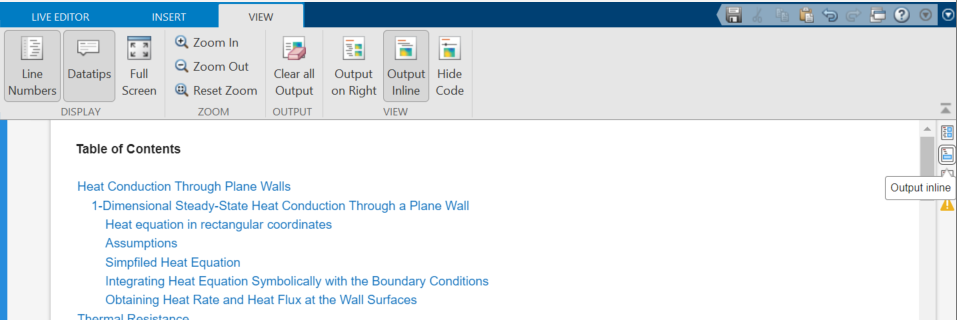

Next to the hands-on exercises, you will see   symbol.

## 1-Dimensional Steady-State Heat Conduction Through a Plane Wall

Let's consider the system below. We want to obtain the temperature profile within the wall and heat flux and heat rate through the walls.

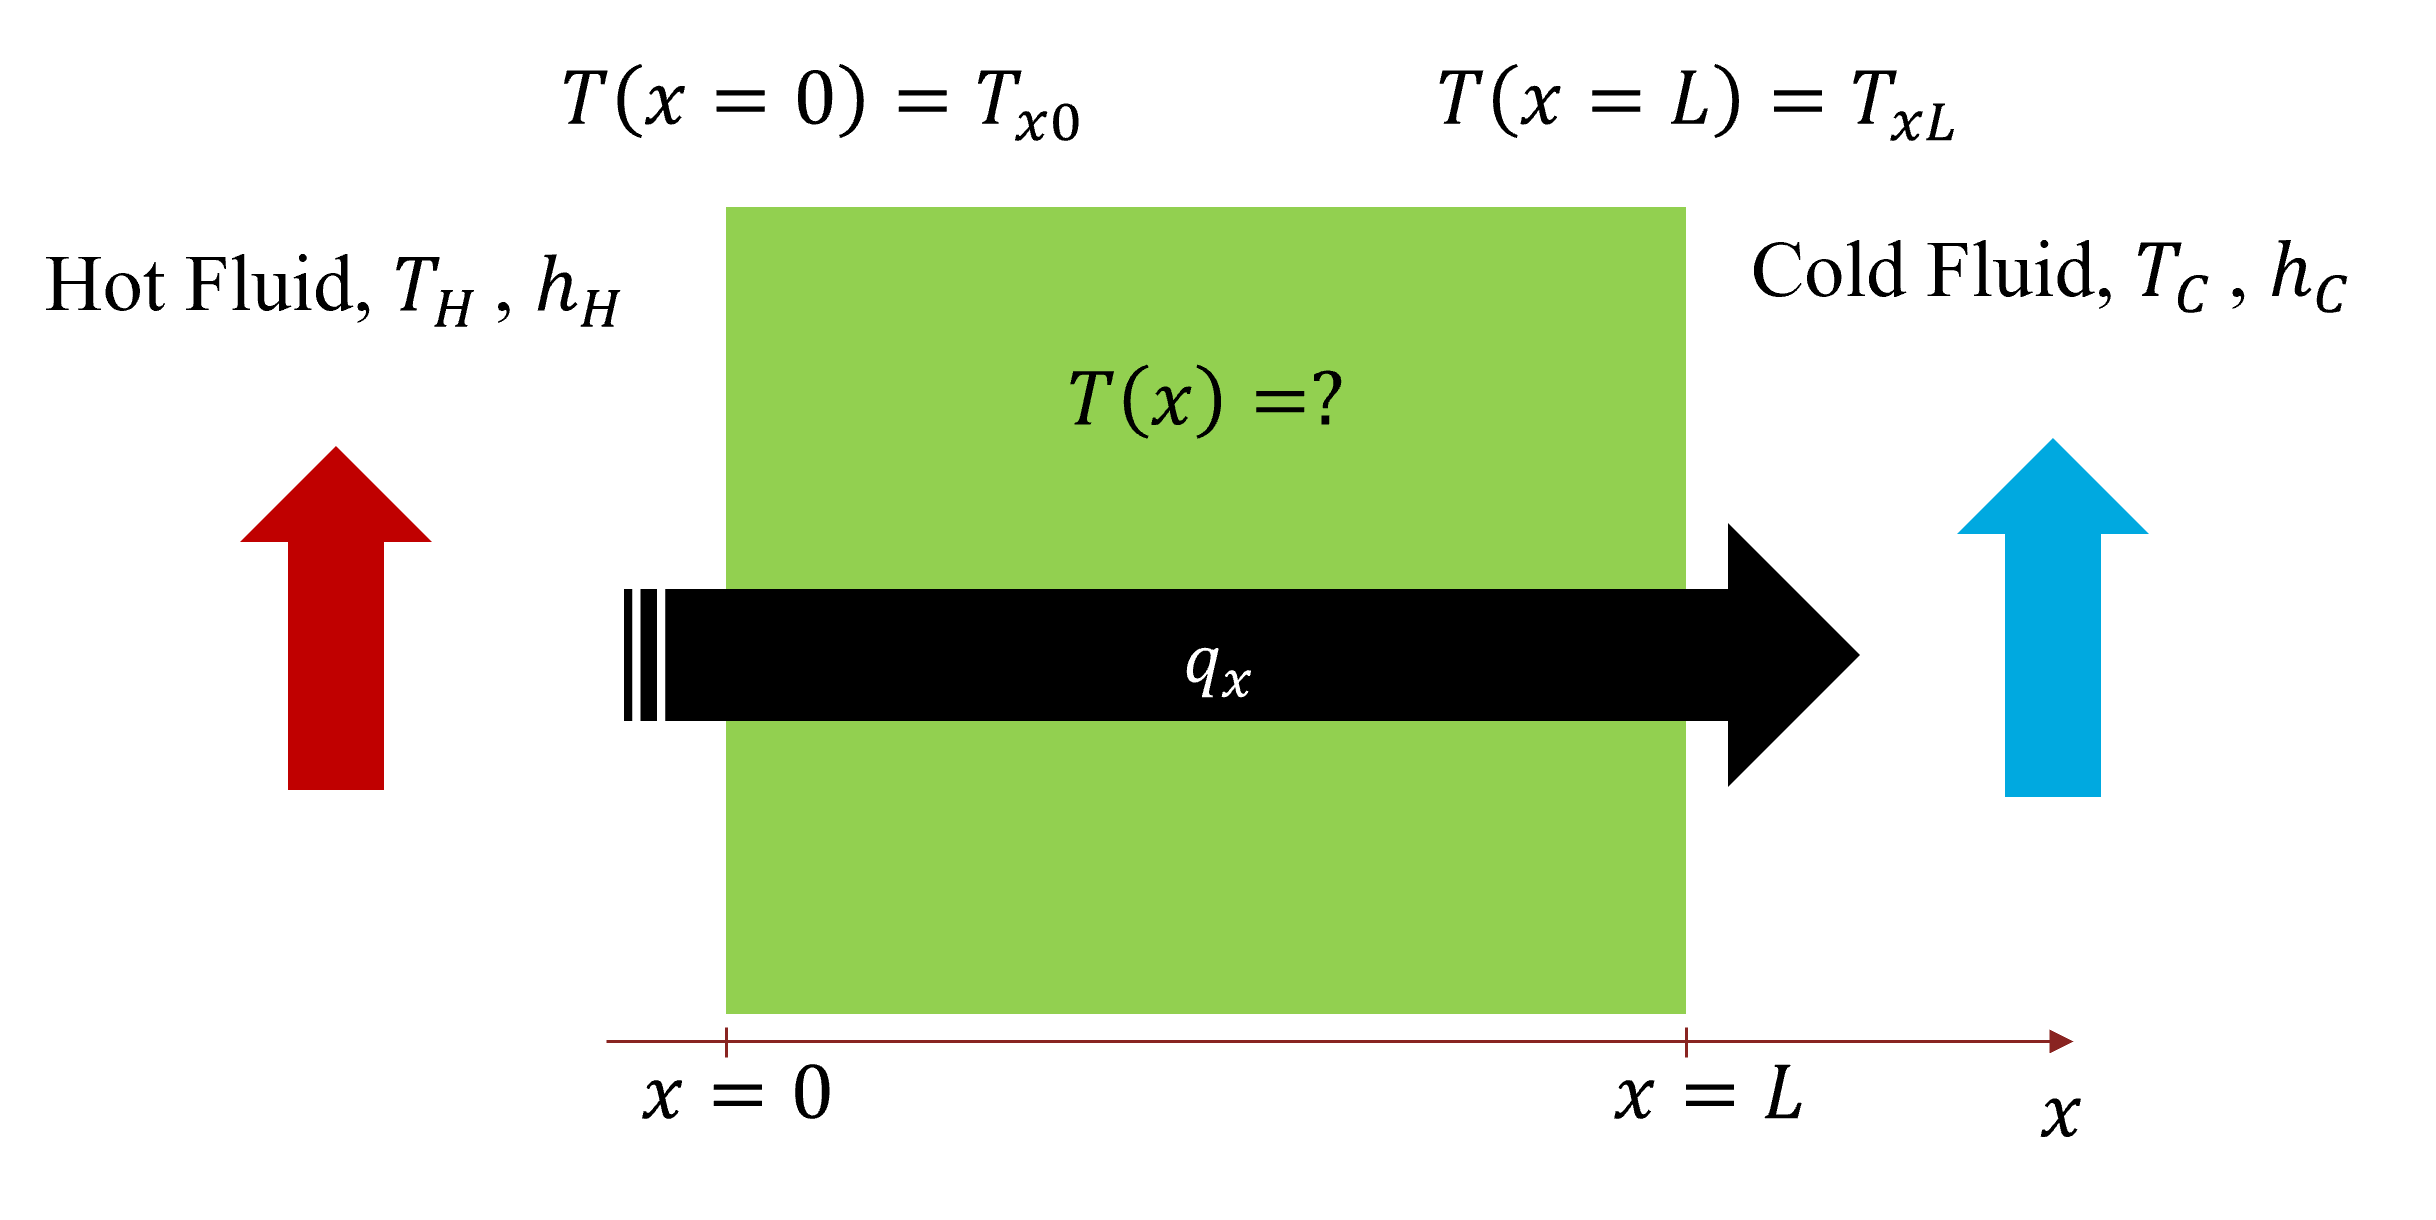

In this system, a conductive plane wall is surrounded by moving fluid on both sides at different temperatures. At steady-state, 1-dimensional heat transfer with no generation occurs in x-direction. The heat is transferred from the moving hot fluid at temperature $T_{H\;}$to the wall at temperature $T_{\textrm{x0}\;}$via convection, the same amount of heat is conducted through the wall of thickness,$L$ and the same amount is convected to the cold fluid of temperature $T_C$ from the other side of the wall at temperature, $T_{\textrm{xL}}$.

In order to obtain the temperature profile, we need to integrate the heat equation in rectangular coordinates after making appropriate simplifications and assigning boundary conditions.

### **Heat equation in rectangular coordinates**


$$\frac{\partial }{\partial x}\left(k\frac{\partial T}{\partial x}\right)+\frac{\partial }{\partial y}\left(k\frac{\partial T}{\partial y}\right)+\frac{\partial }{\partial z}\left(k\frac{\partial T}{\partial z}\right)+\dot{q} =\rho c_{p\;} \frac{\partial T}{\partial t}$$


where $T\left(x,y,z,t\right)$ is the temperature profile, $\dot{q}$ is the heat generation within the system, $k\;$is the thermal conductivity, $\rho$ is the density and $c_{p\;}$is the specific heat of the material [1]. 

### **Assumptions**

- No heat generation $\rightarrow$ $\dot{q} =0$

- Steady-state $\rightarrow$ $\frac{\partial T}{\partial t}$=0

- 1-D heat transfer in x direction $\rightarrow$ $T\left(x\right)\;\textrm{and}\;\frac{\partial T}{\partial y}=0\;\textrm{and}\;\frac{\partial T}{\partial z}=0$

### **Simplified Heat Equation**

With the assumptions above, the heat equation reduces to:


$$\frac{d}{dx}\left(k\;\frac{dT}{dx}\right) = 0$$


with constant thermal conductivity within the wall, this equation becomes:


$$\frac{d}{dx}\left(\frac{dT}{dx}\right) = 0$$


### **Integrating Heat Equation Symbolically with the Boundary Conditions**

  **Exercise 1: **

Define $\frac{d}{dx}\left(\frac{dT}{dx}\right) = 0$ equation symbolically and integrate it twice with the boundary conditions $T\left(x=0\right)=T_{\textrm{x0}}$ and $T\left(x=L\right)=T_{\textrm{xL}}$.

**Step 1:** In the gray code block below, using [syms ](https://www.mathworks.com/help/symbolic/syms.html)define symbolic variables for the equation, $T\left(x\right)$ and the values of the boundary conditions, T_x0 and T_xL and the thickness of the wall, L. 

Example:

%write your code here



**Step 2: **Symbolically define the differential equation $\frac{d}{dx}\left(\frac{dT}{dx}\right) = 0$ using [diff ](https://www.mathworks.com/help/symbolic/sym.diff.html)function. Keep in mind that this is a 2. order differential equation. You can pass the order of the differential equation in diff function's argument.

Example:

**Step 3: **Symbolically define the equations for the boundary conditions $T\left(x=0\right)=T_{\textrm{x0}}$ and $T\left(x=L\right)=T_{\mathrm{xL}}$

Example:

**Step 4: **Solve the differential equation defined in Step 2 with the boundary conditions defined in Step 3 using [dsolve ](https://www.mathworks.com/help/symbolic/dsolve.html)function.

Example:

Temperature changes linearly within the wall.

### **Obtaining Heat Rate and Heat Flux at the Wall Surfaces**

  **Exercise 2:**

Using Fourier's Law, obtain the heat conduction rate at the walls:


$$q_x = -kA\frac{dT}{dx}$$


where$A$ is the area of the wall normal to the direction of the heat transfer. 

**Step 1:  **Symbolically define qx, k and A. 

**Step 2: **Symbolically differentiate the temperature profile, T(x) obtained in Exercise 1 and symbolically obtain heat rate, $q_x = -kA\frac{dT}{dx}$. 

**Step 3: **Heat flux is heat rate per area (A). Symbolically obtain heatflux.

In this case, as we expected, heat rate is independent of $x$. The amount of heat conducted is the same for both walls.This value is also equal to the heat convection to and from the walls at steady-state.

# Thermal Resistance

Looking at the heat rate equation, we can find an analogy between heat diffusion and electrical conduction for this special case of steady-state heat transfer through 1-D planar wall with constant thermal properties and no heat generation [2]. In electrical systems, electrical resistance is governed by Ohm's law ($V=I\;R$), equals to voltage difference across the resistor divided by current passing through. In thermal systems, thermal resistance is temperature difference (driving force) divided by heat rate. This analogy yields thermal resistance for conduction through a wall as 


$$R_{\textrm{cond}} =\frac{T_{\textrm{x0}} -T_{\textrm{xL}} }{q_x }=\frac{L}{\textrm{kA}}$$


Thermal resistance can also be defined for heat transfer by convection at a surface using Newton's law of cooling. For example for the hot fluid side, $q=\textrm{hA}\left(T_{\textrm{x0}} -T_H \right)$ where $q$ is the heat rate, $A$ is the normal surface area in the path heat flow.


$$R_{\textrm{conv}} =\frac{T_{\textrm{x0}} -T_H }{q}=\frac{1}{\textrm{hA}}$$


Since in the above system the heat rate is constant, it can be obtained in different forms:


$$q_x =\frac{T_H -T_{\textrm{x0}} }{\frac{1}{h_H A}}=\frac{T_{\textrm{x0}} -T_{\textrm{xL}} }{\frac{L}{\textrm{kA}}}=\frac{T_{\textrm{xL}} -T_C }{\frac{1}{h_C A}}=\frac{T_H -T_C }{R_{\textrm{tot}} }$$


where $R_{\textrm{tot}\;} \;$is the total thermal resistance and since convection and conduction resistances are in series, they can be added to obtain the total thermal resistance, similar to combination electrical resistances in series:


$$R_{\textrm{tot}} =\frac{T_H -T_C }{q_x }=\frac{\left.{\left(T\right.}_H -T_{x0} \right)+\left(T_{\textrm{x0}} -T_{\textrm{xL}} \right)+\left(T_{\textrm{xL}} -T_C \right)}{q_x }=\frac{1}{h_H A}+\frac{L}{\textrm{kA}}+\frac{1}{h_C A}$$


You can see that similar to electrical resistance, you can evaluate the inverse of total resistance of parallel components ($R_1 ,R_{2,} ,R_3 ,\ldotp \ldotp \ldotp ,R_n$) by the sum of their inverses. 


$$\frac{1}{R_{\textrm{tot}} }=\frac{1}{R_1 }+\frac{1}{R_2 }+\frac{1}{R_3 }+\ldotp \ldotp \ldotp +\frac{1}{R_n }$$


# Heat Conduction Through Composite Walls

Thermal resistances could be used with composite walls that consist of different layers of materials. Consider the system below with different thermal conductivities, wall thicknesses and interface temperatures:

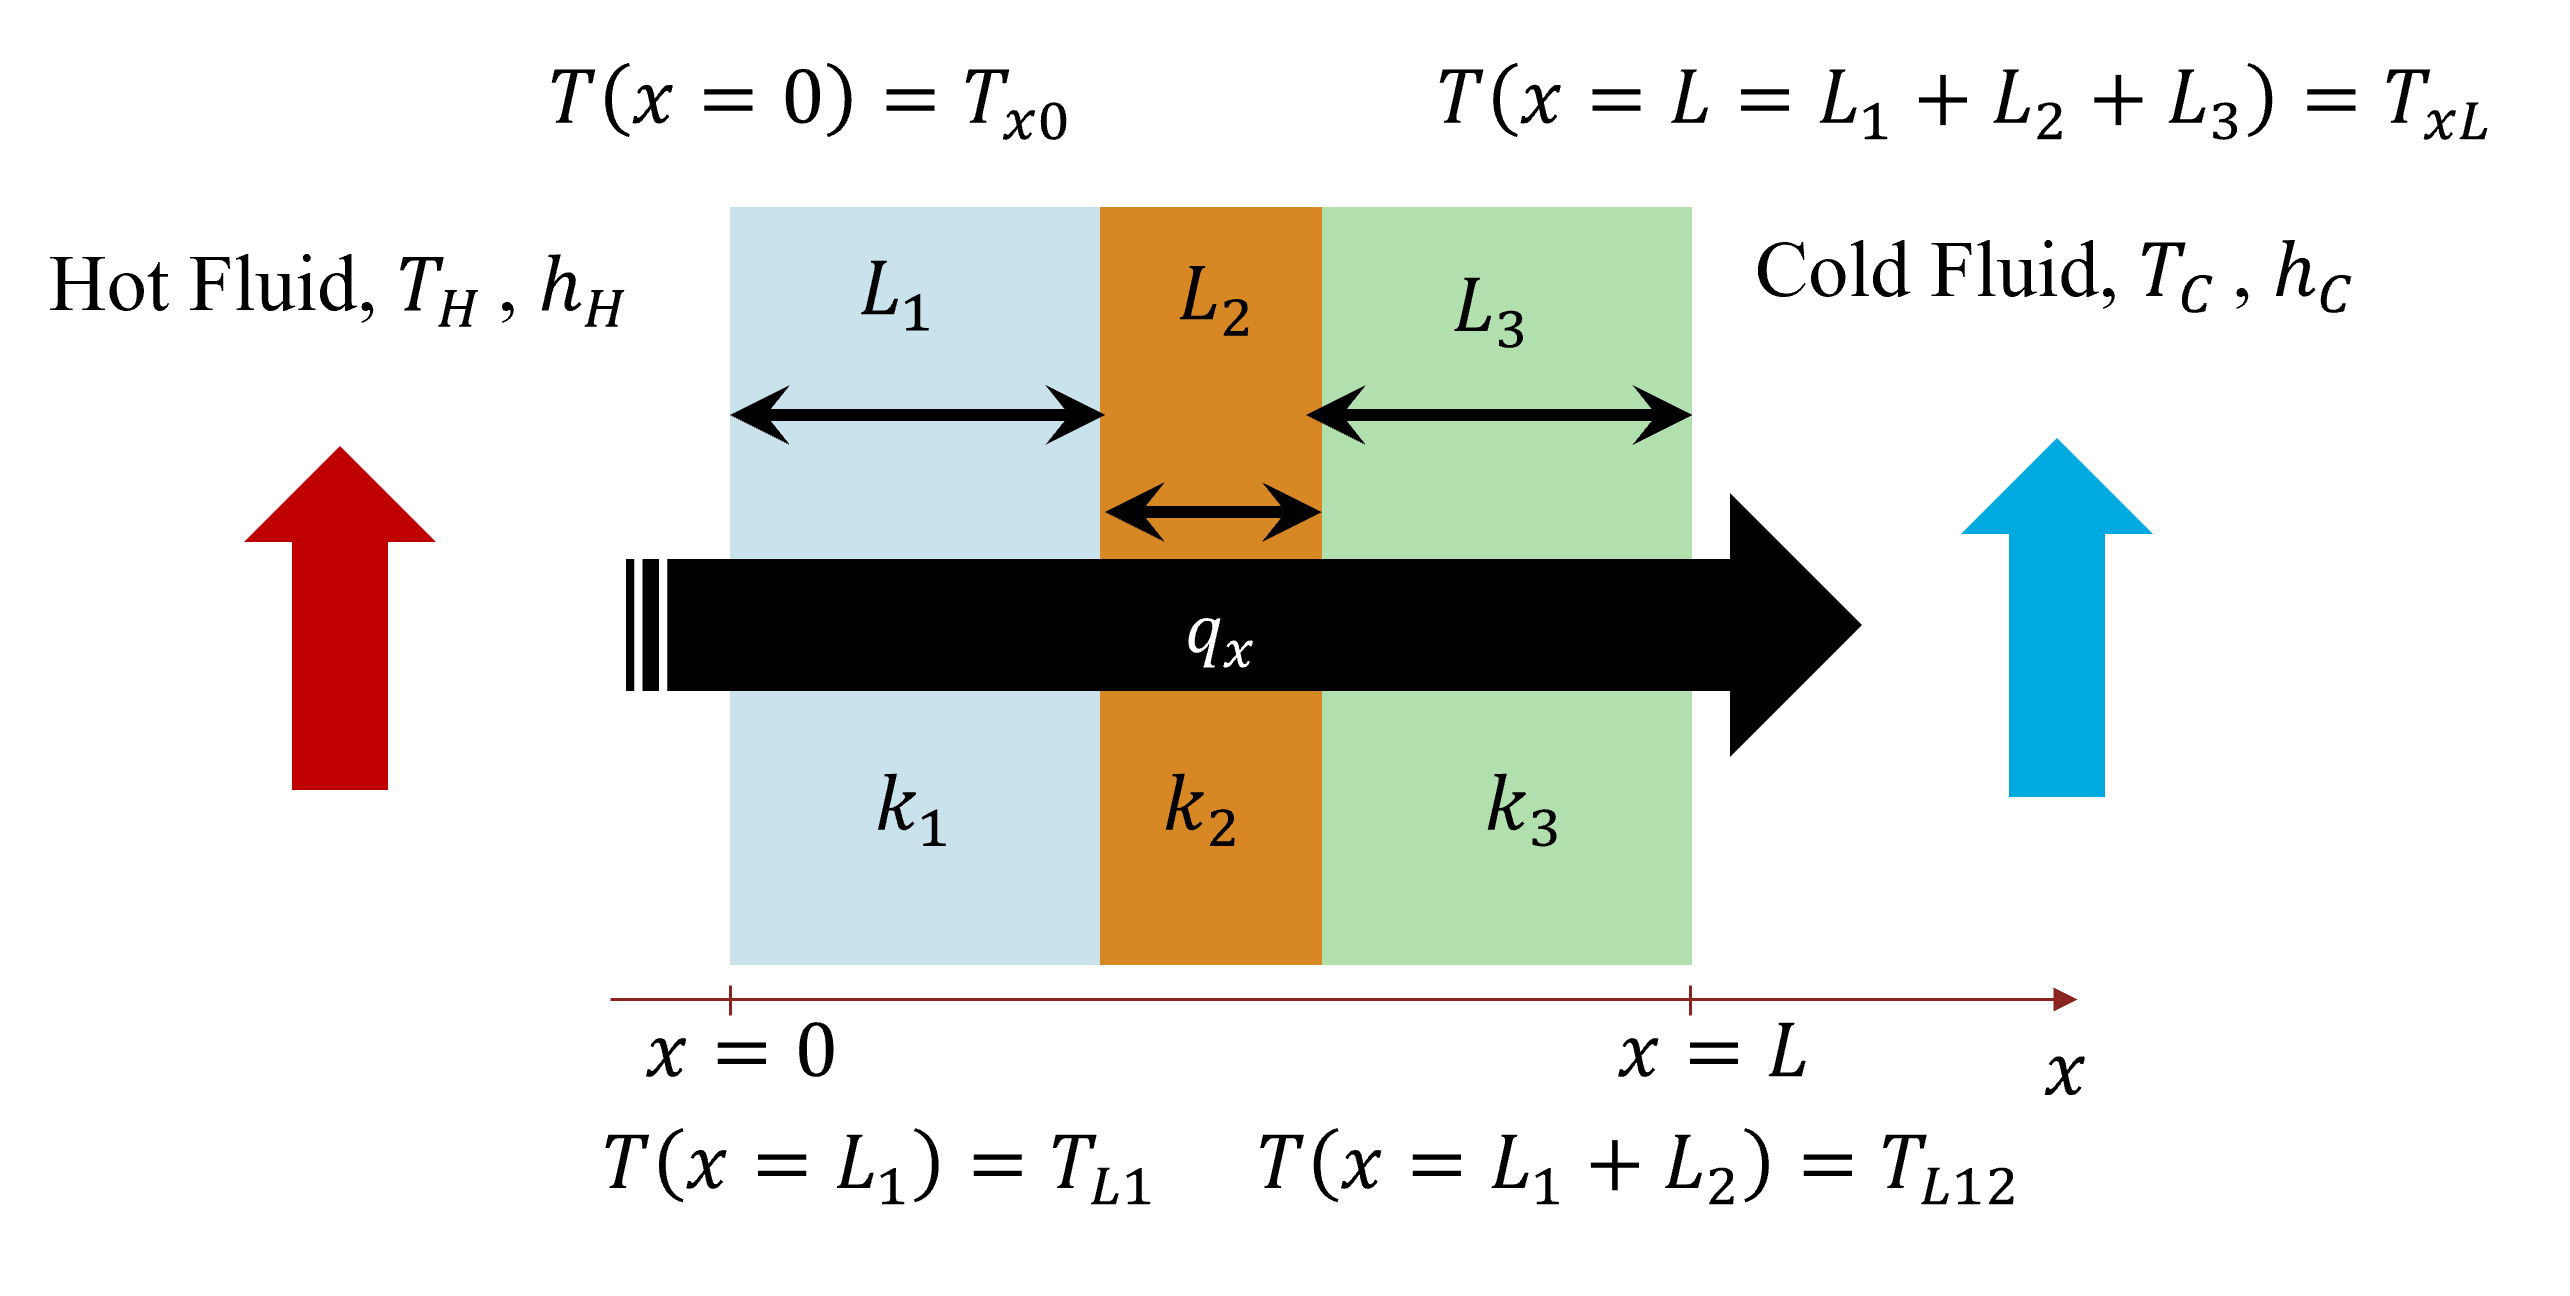

Heat transfer rate through the wall is


$$q_{x\;} =\frac{T_H -T_C }{\sum R_{\textrm{tot}} }=\frac{T_H -T_C }{\frac{1}{h_H A}+\frac{L_1 }{\;k_1 A}+\frac{L_2 }{\;k_2 A}+\frac{L_3 }{\;k_{3\;} A}+\frac{1}{h_C A}}=\frac{T_H -T_{\textrm{x0}} }{\frac{1}{h_H A}}=\frac{T_x -T_{\textrm{L1}} }{\frac{L_1 }{k_1 A}}=\frac{T_{\textrm{L1}} -T_{\textrm{L12}} }{\frac{L_2 }{k_2 A}}=\frac{T_{\textrm{L12}} -T_{\textrm{xL}} }{\frac{L_3 }{k_3 A}}=\frac{T_{\textrm{xL}} -T_C }{\frac{1}{h_C A}}=\textrm{UA}\Delta T$$


where U is the overall heat transfer coefficient.

If the system consists of horizontal partitions as well, multiple equivalent circuit representations of the same system arises that consists of series and parallel circuits. To find which circuit representation is more accurate, we can also model heat transfer in 2-D. The following example shows how 2-D conduction in composite walls could be modeled with Partial Differential Equation Toolbox™.

## Wall with Horizontal and Vertical Partitions - Series and Parallel Equivalent Circuit Models  

Consider the system below with the following properties. It has three layers in horizontal direction. The middle layer partitions to three layers with the same height equal to 1/3 of the total height of the wall. We calculate the heat rate across the insulated walls at steady-state for both equivalent circuit representations of the same system. Note that the values below are picked for demonstration only. 

% Temperature [K]
Tx0 = 300; % Left surface
TxL = 270; % Right surface
deltaT=Tx0-TxL;

% Thickness [m]
L1= 1.0; % Layer 1
L2= 1.0; % Layer 2
L3= 1.0; % Layer 3 

% Thermal conductivity [W/(m*K)]
k1= 1; % Material 1  [W/(m*K)]
k2a=1; % Material 2a [W/(m*K)]
k2b=3; % Material 2b [W/(m*K)]
k2c=9; % Material 2c [W/(m*K)]
k3= 1; % Material 3  [W/(m*K)]

% Wall total surface area  [m^2]
A = 1; 

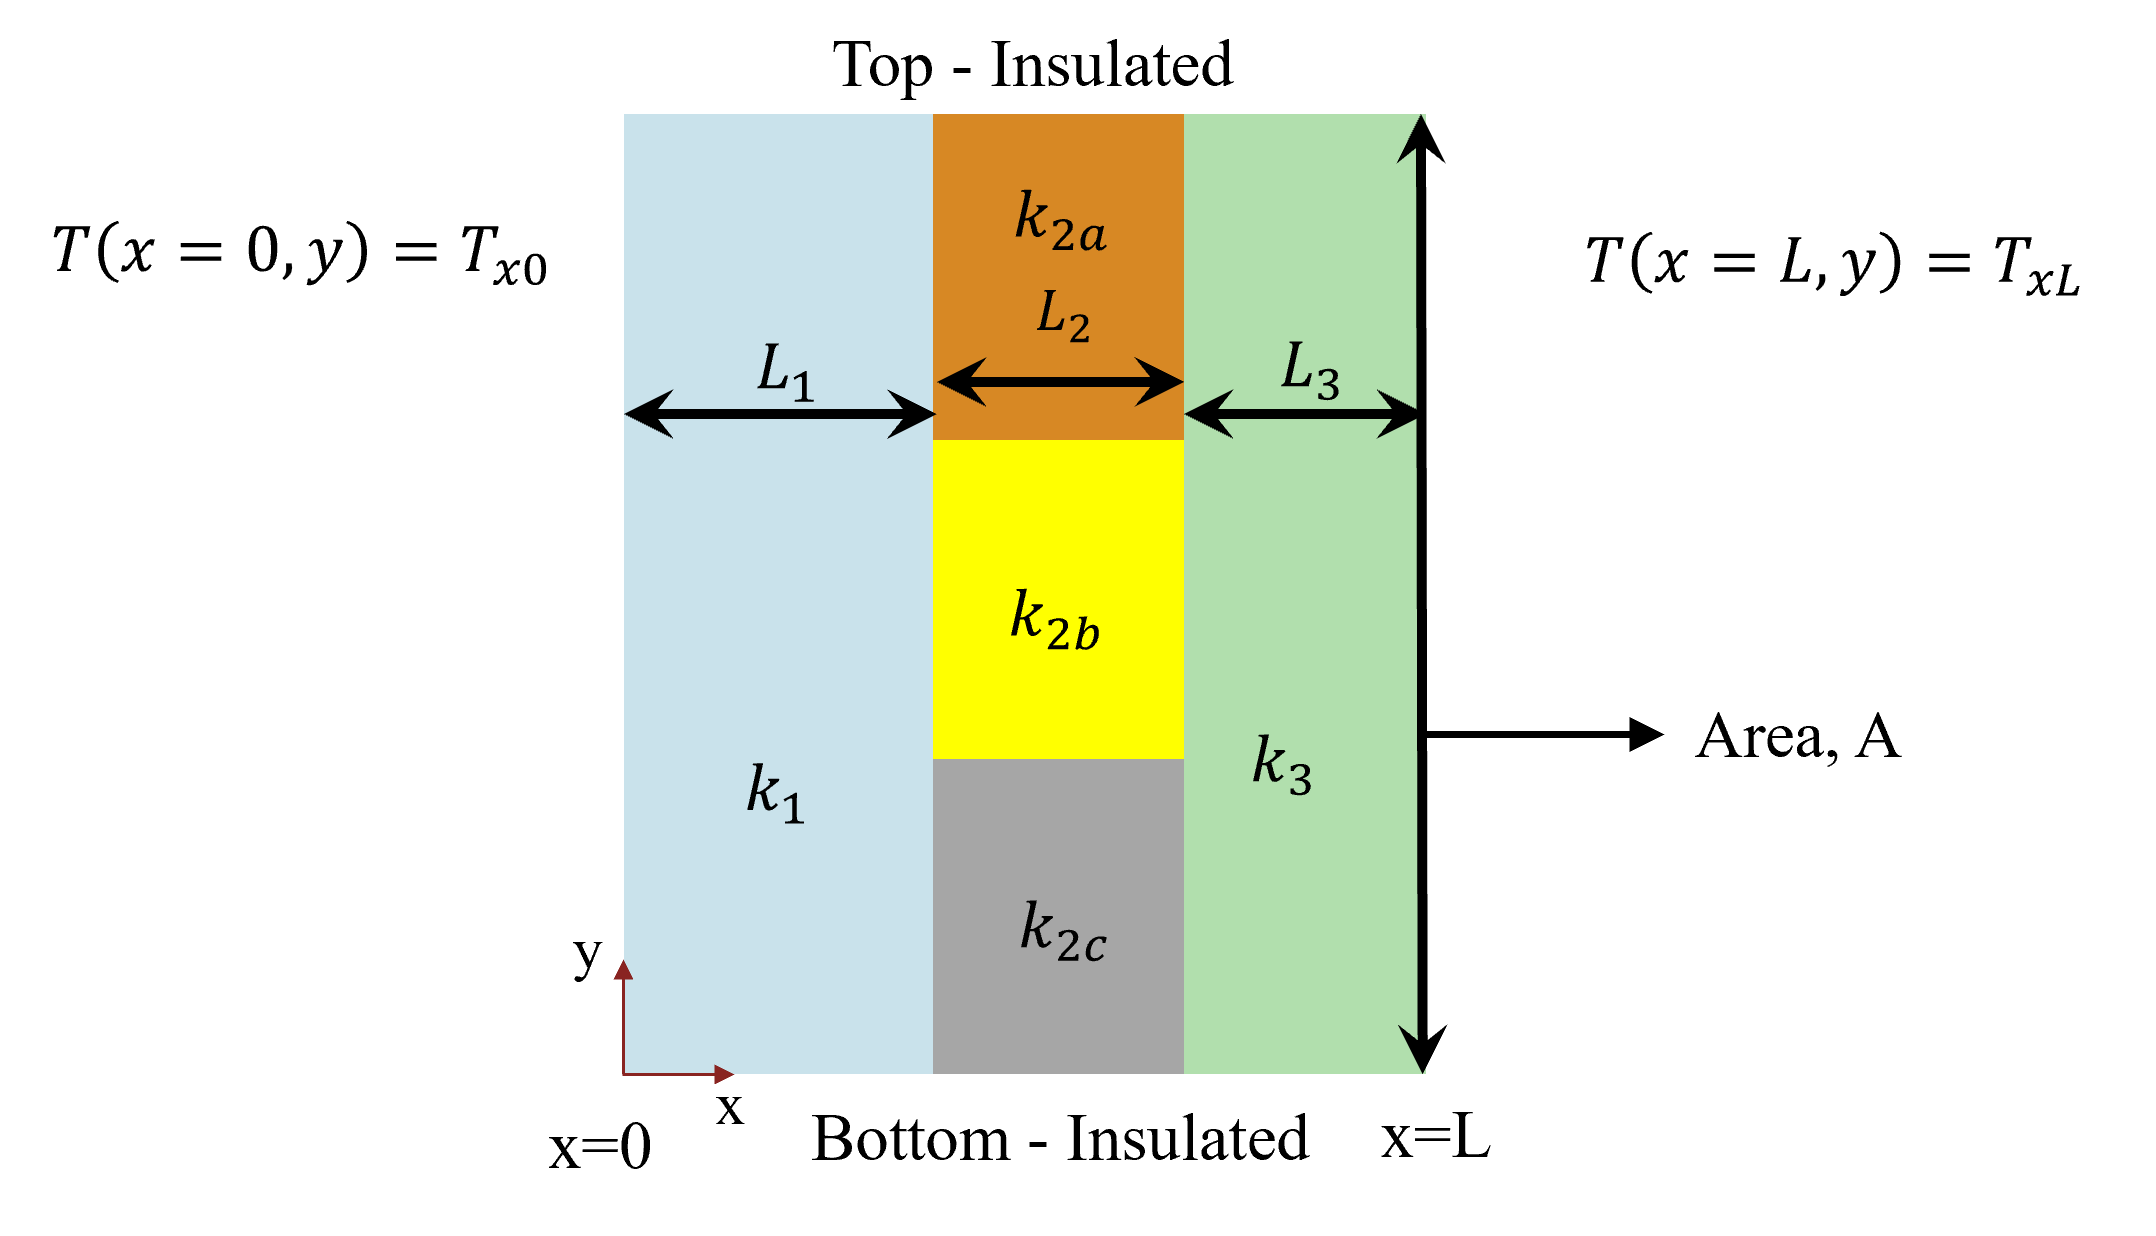

Since the material is horizontally partitioned and thermal conductivities are different, there are 2 overall alternatives to represent this system with equivalent circuits. The heat transfer is in 2-D, but 1-D models are good approximations. Our goal is finding out which equivalent circuit representation is closer to the 2-D model.

**Model 1:** Assume that vertical surfaces (normal to x direction) are at the same temperature. Therefore, the thermal resistance in the middle layer are in parallel to each other, and then in series with left and right layers.

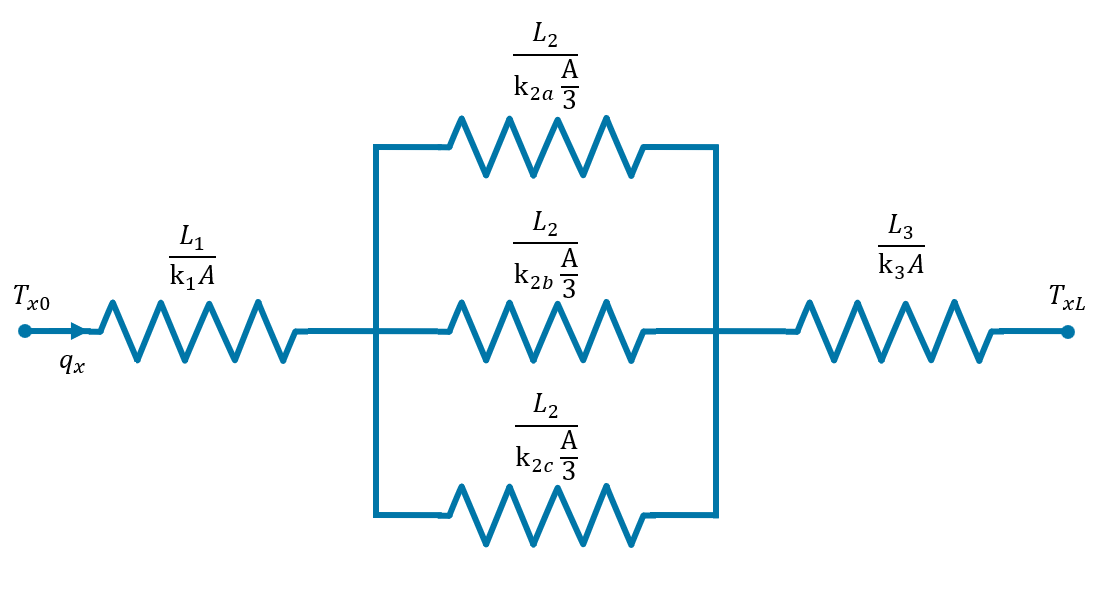

**Total resistance for model 1:**


$$R_{\textrm{tot}\;} =\sum R_{i\;} =\frac{T_{\textrm{x0}\;} -T_{\textrm{xL}} }{q_x }$$
 


$$R_{\textrm{tot}\;} =R_1 +{\left\lbrack \frac{1}{R_{2a} }+\frac{1}{R_{2b} }+\frac{1}{R_{2c} }\right\rbrack }^{-1} +R_3 =\frac{L_1 }{k_1 \times A}+{\left\lbrack \frac{k_{2a} \frac{A}{3}}{L_2 }+\frac{k_{2b} \frac{A}{3}}{L_2 }+\frac{k_{2c} \frac{A}{3}}{L_2 }\right\rbrack }^{-1} +\frac{L_3 }{k_3 \times A}\;$$


% Model 1 - Calculation of overall resistance
R1 =L1/(k1 * A   );
R2a=L2/(k2a*(A/3));
R2b=L2/(k2b*(A/3));
R2c=L2/(k2c*(A/3));
R3 =L3/(k3 * A   );
Rtot1=R1 + 1/(1/R2a+1/R2b+1/R2c) + R3;
% Heat transfer rate for Model 2 [W]
q1=deltaT/Rtot1

**Model 2: **Assume to heat transfer across the surfaces parallel to x direction.Therefore, there are three overall parallel thermal channels in x direction.

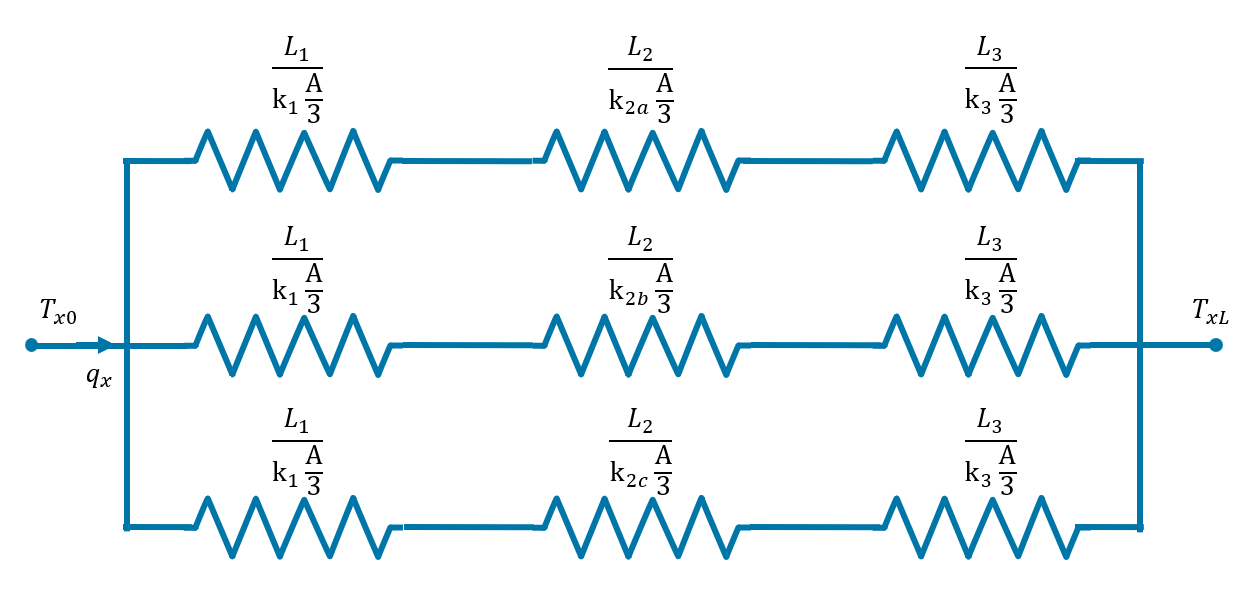

**Total resistance for Model 2:**

$R_{\textrm{tot}}^{-1} ={\left\lbrack \frac{L_1 }{k_1 \times \left(\frac{A}{3}\right)}+\frac{L_{2a} }{k_{2a} \times \left(\frac{A}{3}\right)}+\frac{L_3 }{k_3 \times \left(\frac{A}{3}\right)}\right\rbrack }^{-1} +{\left\lbrack \frac{L_1 }{k_1 \times \left(\frac{A}{3}\right)}+\frac{L_{2b} }{k_{2b} \times \left(\frac{A}{3}\right)}+\frac{L_3 }{k_3 \times \left(\frac{A}{3}\right)}\right\rbrack }^{-1}$+${\left\lbrack \frac{L_1 }{k_1 \times \left(\frac{A}{3}\right)}+\frac{L_{2c} }{k_{2c} \times \left(\frac{A}{3}\right)}+\frac{L_3 }{k_3 \times \left(\frac{A}{3}\right)}\right\rbrack }^{-1}$

% Model 2 - Calculation of overall resistance
Rtot2=1/(...
    1/(3*R1+R2a+3*R3)+...
    1/(3*R1+R2b+3*R3)+...
    1/(3*R1+R2c+3*R3));
% Heat transfer rate for Model 2 [W]
q2=deltaT/Rtot2

## 2-D Model with Partial Differential Equation Toolbox

We will now use the Partial Differential Equation (PDE) Toolbox to solve the same problem in the previous section in 2-D and 3-D and compute the heat flux through the wall. Stationary conductive heat transfer is modeled mathematically by a partial differential equation. The PDE Toolbox uses Finite Element Analysis (FEA) to approximately solve this equation in 2 and 3 dimensions. We will first solve this problem in 2D. 

#### Create geometry

  **Exercise 3: **

Create the 2D constructive solid geometry (CSG), which consists of multiple rectangles, using the [decsg](https://www.mathworks.com/help/pde/ug/decsg.html) function in PDE Toolbox. 

**Step 1:** To [define a rectangle programmatically](https://www.mathworks.com/help/pde/ug/create-geometry-at-the-command-line.html#buk782l) in PDE Toolbox, we define a 10-element column vector where:

Using this synax, create five 10-element column vectors to represent the rectangular regions that appear in the 2D geometry. (Hint: start at the lower left vertex of each rectangle and work counter-clockwise.) 

**Define 4, and have them define the 5th**

**Step 2: **Combine these column vectors into a 10x5 matrix named "gd". 

**Step 3: **Create names for the shapes by creating a single character array with whose rows contain the names of each rectangle, and then take the transpose. Use the [char](https://www.mathworks.com/help/matlab/ref/char.html) function to create the character array. 

**Step 4:** Obtain the final geometry by writing a set of characters that unions all 5 rectangles. (Hint: use the rectangle names you created in the character array in Step 3, and use '+' to denote a union.) 

sf = 

**Step 5:** Create the geometry by inputing the geometry matrix from Step 2, the formula from Step 4, and the names from Step 3 into the [decsg](https://www.mathworks.com/help/pde/ug/decsg.html) function. Make sure to give the output a name.

g = decsg(gd, sf, ns)

**Step 6:** Visualize your newly created geometry by using [pdegplot](https://www.mathworks.com/help/pde/ug/femodel.pdegplot.html). Use Name-Value pairs to plot the edge and face labels. 

#### Set up the PDE model

  **Exercise 4: **

Set up a model in PDE Toolbox to conduct the thermal steady-state analysis. To conduct the analysis, we will also need to define boundary conditions and material properties as per the problem definition, and generate a finite element mesh. 

**Step 1: **Create an [femodel](https://www.mathworks.com/help/pde/ug/femodel.html) with analysis type "thermalSteady" and the geometry you created in Exercise 3. 

**Step 2: **Using the [edgeBC](https://www.mathworks.com/help/pde/ug/edgebc.html) function, set the temperatures on the left and right side of the domain to Tx0 and TxL, respectively. (Hint: use the output of pdegplot from Exercise 3 Step 6 to determine the numbered labels that correspond to the left and right edges of the boundary.)

**Define the left, let them define the right**

**Step 3: **Using the [edgeLoad](https://www.mathworks.com/help/pde/ug/edgeload.html) function, set the heat flux to 0 on the top and bottom edges of the domain. (Hint: use the output of pdegplot from Exercise 3 Step 6 to determine the numbered labels that correspond to the top and bottom edges of the boundary.)

**Define the top, let them define the bottom**

q1 = 13.4483

**Step 4: **Using the materialProperties function, set each rectangular region to its correct thermal conductivity value. (Hint: use the output of pdegplot from Exercise 3 Step 6 to determine the numbered labels that correspond to each rectangular face.)

**Do 4, let them do the 5th**

**Step 5:** Generate the finite element mesh by using the [generateMesh](https://www.mathworks.com/help/pde/ug/pde.pdemodel.generatemesh.html) function, and set the "Hmax" Name-Value pair to 0.05. 

**Step 6:** Visualize the mesh using the [pdemesh](https://www.mathworks.com/help/pde/ug/femodel.pdemesh.html) function. 

#### Solve and plot solution

  **Exercise 5: **

Solve the steady state thermal problem and visualize the solution. Evaluate the heat rate through the wall on the right side. 

**Step 1: **Solve the thermal steady problem using the [solve](https://www.mathworks.com/help/pde/ug/pde.femodel.solve.html) function. This returns a struct containing several fields. Store the "Temperature" field into a new variable. 

**Step 2:** Visualize the temperature in a 2D heatmap using the [pdeplot](https://www.mathworks.com/help/pde/ug/pdeplot.html?s_tid=doc_ta) function. Set the "Colormap" Name-Value pair to "turbo".  

**Step 3: **Evaluate the heat rate through the wall on the right side using the function "[evaluateHeatRate](https://www.mathworks.com/help/pde/ug/pde.steadystatethermalresults.evaluateheatrate.html)". Divide this value by the cross-sectional area of the wall to estimate the heat flux leaving the right wall. (Hint: you will need the numbered label for the right edge of the wall when using the "evaluateHeatRate" function.) 

q2 = 12.3559

**Reflect:** In this case, which model represents the composite wall better?

The results of computational solution gives the option to inspect the system in more details. For example, you can evaluate the heat flux within the wall.

[qx,qy] = evaluateHeatFlux(results);

Unrecognized function or variable 'results'.

figure
hold on
pdegplot(dl,'EdgeLabels', 'on', 'FaceLabels', 'on');
msh= results.Mesh;
pdeplot(msh,FlowData=[qx qy])
title("Heat Flux, Steady State Solution")

The heat flux in middle sections parts may be different because of the their thermal conductivities. How does the thermal conductivity changes the heat flux that passing through the section? 

## 3-D Model with PDE Toolbox

We will now use the Partial Differential Equation (PDE) Toolbox to solve the 3D heat transfer problem and compute the heat flux through the wall. Stationary conductive heat transfer is modeled mathematically by a partial differential equation. The PDE Toolbox uses Finite Element Analysis (FEA) to approximately solve this equation in 2 and 3 dimensions. It is easy to transform the problem into 3D using the PDE Toolbox, but it takes longer to solve because there are more degrees of freedom. 

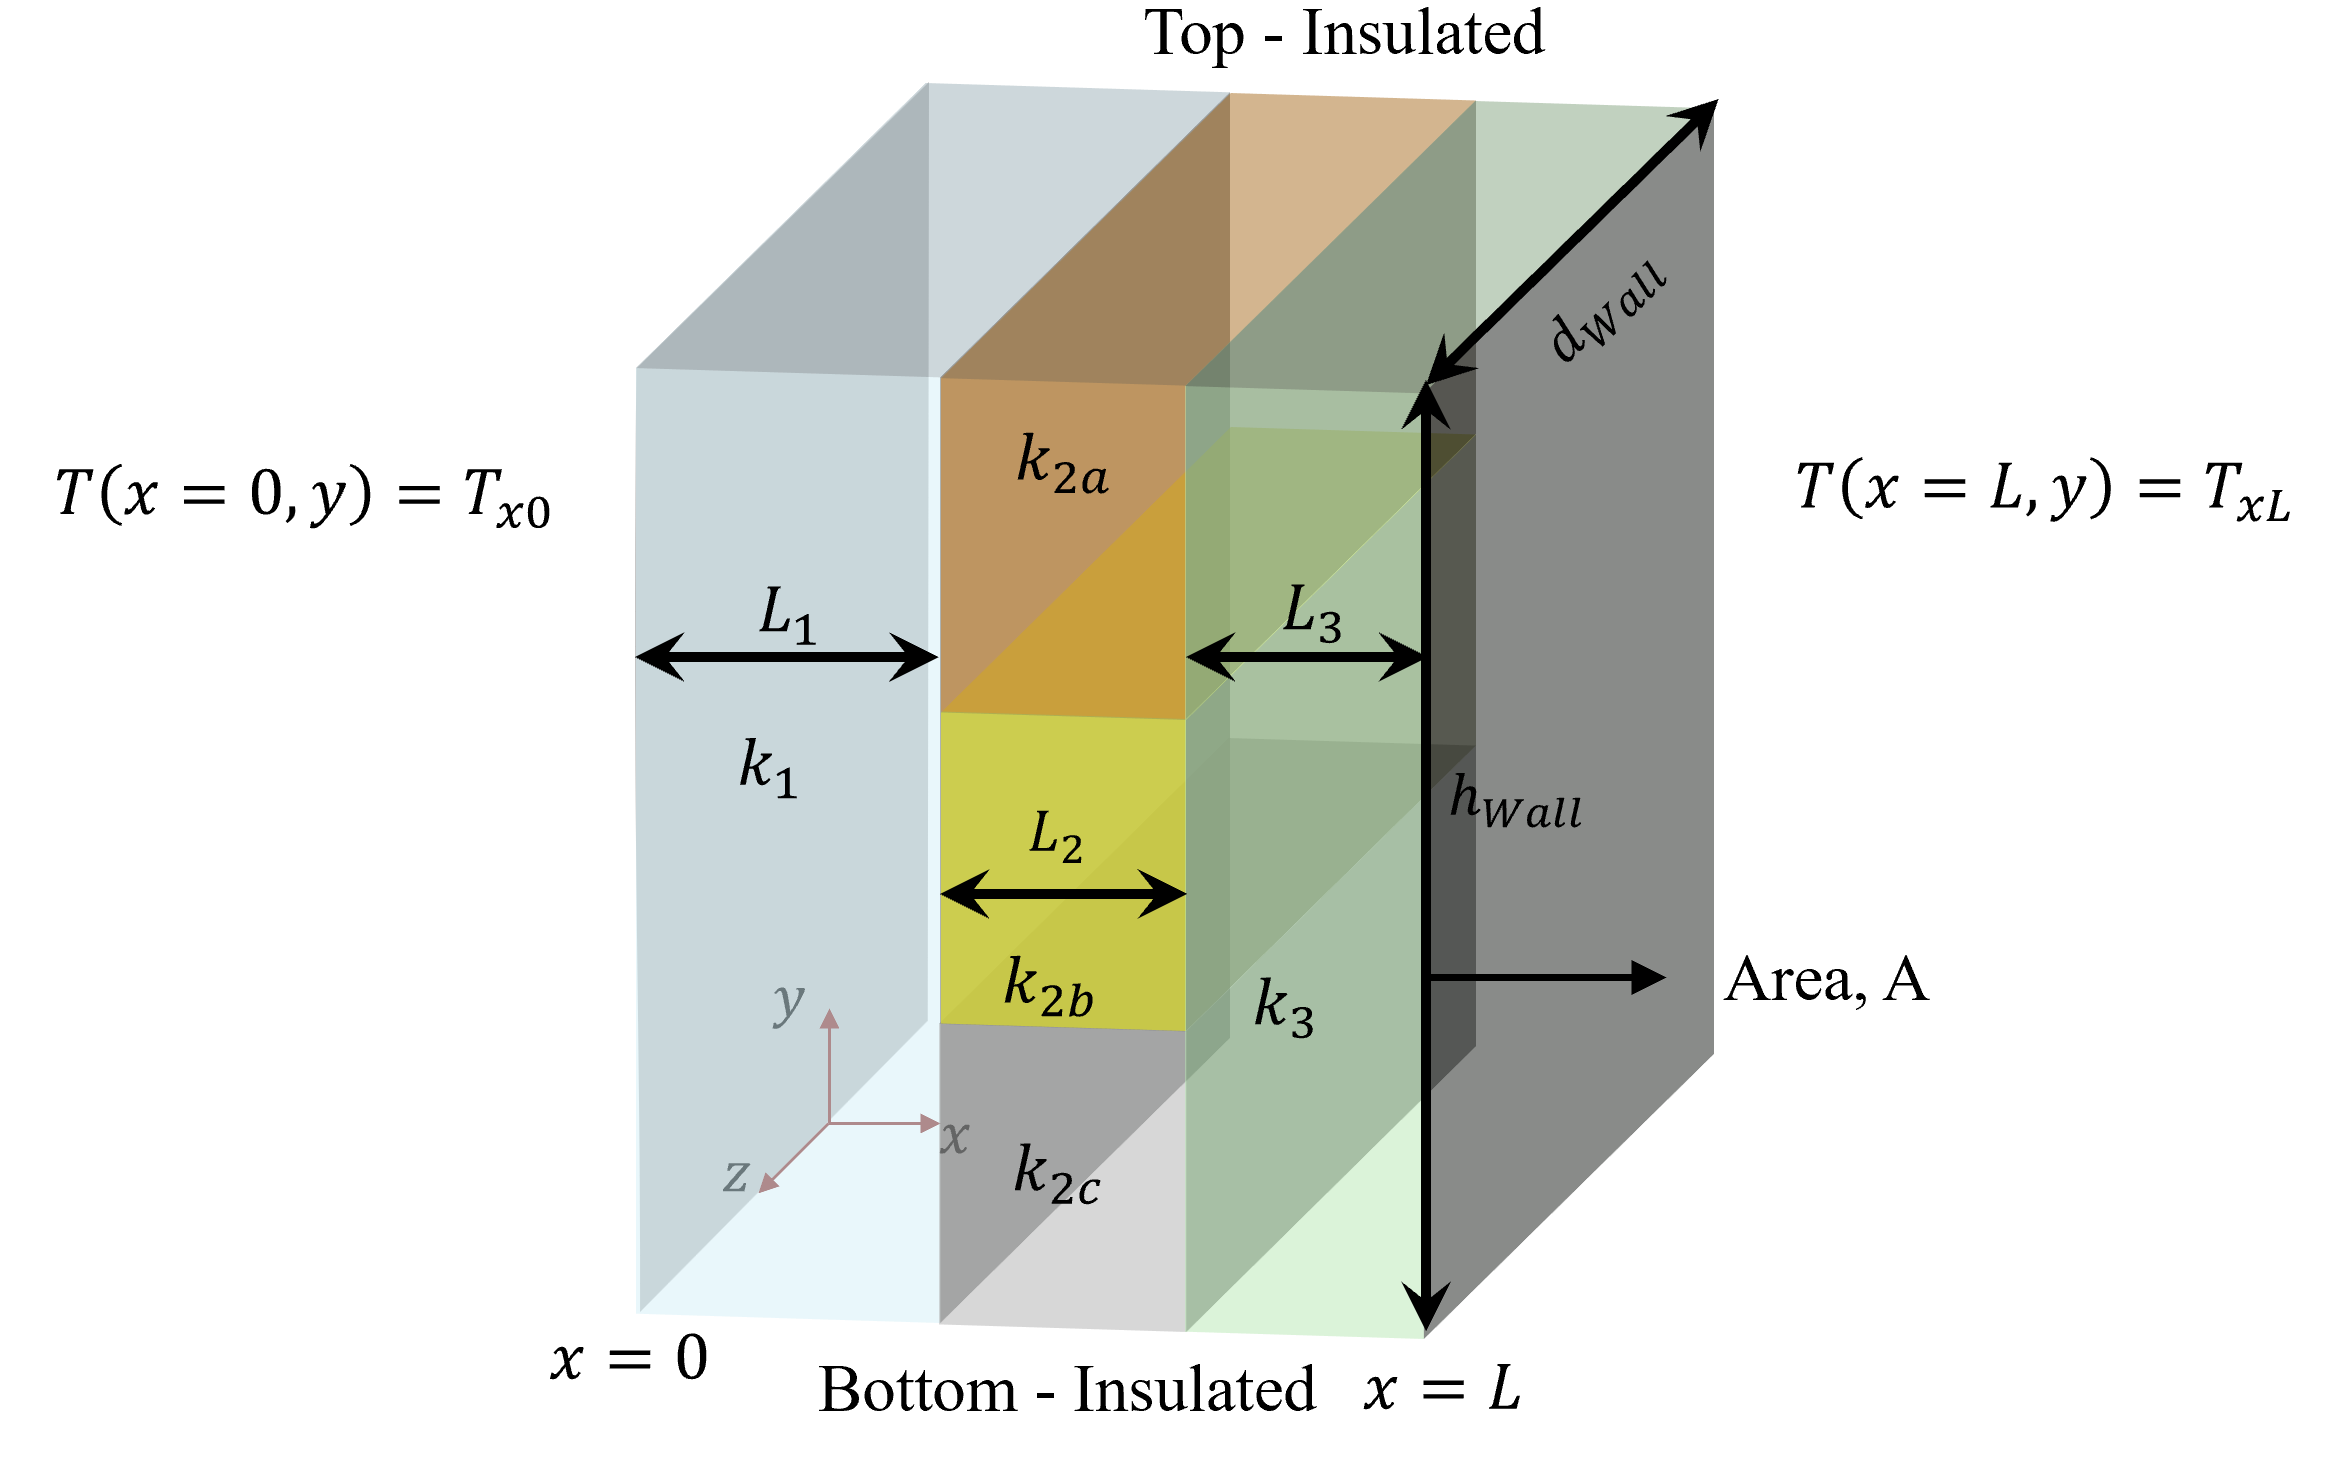

#### Create geometry

Extrude the 2D geometry in the z direction to create the 3D geometry. 

dwall=1;
hwall=A/dwall; 
g3d = extrude(thermalModel.Geometry, dwall);
% visualize geometry
pdegplot(g3d,"FaceAlpha",0.3,"FaceLabels","on","CellLabels","on")
% set angles and up vector for camera view 
view_angles = [135 45];
cam_up=[0 1 0];
view(view_angles); 
camup(cam_up); 

#### Set up the PDE model

thermalModel3d = femodel("AnalysisType","thermalSteady","Geometry",g3d);

#### Define the boundary conditions

thermalModel3d.FaceBC(11) = faceBC("Temperature",Tx0); % Set the temperature on left side to Tx0
thermalModel3d.FaceBC(12) = faceBC("Temperature",TxL); % Set the temperature on left side to TxL
thermalModel3d.FaceLoad(18:20) = faceLoad("Heat",0); % Zero heat flux on bottom boundary
thermalModel3d.FaceLoad(21:23) = faceLoad("Heat",0); % Zero heat flux on top boundary

#### Define the thermal properties of the material

thermalModel3d.MaterialProperties(1) = materialProperties("ThermalConductivity",k2b);
thermalModel3d.MaterialProperties(2) = materialProperties("ThermalConductivity",k2c);
thermalModel3d.MaterialProperties(3) = materialProperties("ThermalConductivity",k2a);
thermalModel3d.MaterialProperties(4) = materialProperties("ThermalConductivity",k1);
thermalModel3d.MaterialProperties(5) = materialProperties("ThermalConductivity",k3);

#### Generate the mesh

thermalModel3d = generateMesh(thermalModel3d);
% visualize the mesh
pdemesh(thermalModel3d); 
axis equal
title("Domain with Finite Element Mesh")
view(view_angles); 
camup(cam_up);

#### Solve and plot solution

results3d = solve(thermalModel3d);
T = results3d.Temperature;
pdeplot3D(results3d.Mesh,"ColorMapData",T); 
axis equal
title("Temperature, Steady State Solution")
view(view_angles); 
camup(cam_up);

Evaluate the heat rate through the wall on the right side

Qn_3d = evaluateHeatRate(results3d,"Face",12)
% divide by the area
q_fea_3d=Qn_3d/(A) 

Visualizing the 3D flux vectors may not be clear in the first try.

[qx,qy,qz] = evaluateHeatFlux(results3d);
pdeplot3D(results3d.Mesh,FlowData=[qx qy qz])
view(view_angles); 
camup(cam_up);

You can sample the results at sparse locations and pick a view along z-axis to have a less crowded image. 

sample_dh=0.1;
[X,Y,Z] = meshgrid(0:sample_dh:L1+L2+L3,0:sample_dh:1,0:sample_dh:1);
[qx,qy,qz] = evaluateHeatFlux(results3d,X,Y,Z);

qx = reshape(qx,size(X));
qy = reshape(qy,size(Y));
qz = reshape(qz,size(Z));
quiver3(X,Y,Z,qx,qy,qz)
axis equal
view (0,90)

Alternatively, you can get a profile view of the result for a X-Y slice at z=0.5.

[Xp,Yp,Zp] = meshgrid(0:sample_dh:L1+L2+L3,0:sample_dh:1,0.5);
[qxp,qyp,qzp] = evaluateHeatFlux(results3d,Xp,Yp,Zp);

qxp = reshape(qxp,size(Xp));
qyp = reshape(qyp,size(Yp));
qzp = reshape(qzp,size(Zp));

pdegplot(g3d,FaceAlpha=0.0)
hold on
quiver3(Xp,Yp,Zp,qxp,qyp,qzp)
hold off
xlim([0 L1+L2+L3])
ylim([0 1])
zlim([0 1])
view(view_angles); 
camup(cam_up);

## Conclusions & Next Steps

Try changing the values of $k_{2a}
$, $k_{2b}
$, and $k_{2c}$. What happens as difference between the thermal conductivities increases? Which approximation is more accurate? Why?

The 1D equivalent thermal circuit models obtain calculations for the heat flux that are close to the 2D and 3D FEA solutions found using the PDE Toolbox. For more realistic problems, for example when the temperature is not a constant value on the boundaries, more accurate 2D and 3D simulations may be needed. You can model heat transfer with thermal resistance approach with Simscape Fluid as well. Check [Heat Conduction Through Iron Rod](https://www.mathworks.com/help/simscape/ug/heat-conduction-through-iron-rod.html) as an example this workflow. 

## References

[1] Frank P. Incropera, David P. DeWitt, Theodore L. Bergman, Adrienne S. Lavine. (2007). "Fundamentals of Heat and Mass Transfer.".

[2] [https://en.wikipedia.org/wiki/Thermal_conductance_and_resistance](https://en.wikipedia.org/wiki/Thermal_conductance_and_resistance) 

*Copyright 2024 The MathWorks, Inc.*